Aquí se implementa el método del Hessiano para 3 dimensiones.

clear
close all
hold off

%Vamos a representar cómo se mueve el centro de la formación

N=8; %Número de robots
iteration=500; %Número de iteraciones
step_size=0.1;
D=1; %Radio de la formación
S=10^-4*[100,1,1;1,1,0;1,0,10]; %Matriz
c0=[20;20;20]; %Posición del centro inicial (initial guess)
r0=[0 0 0]'; %Centro de contaminación (hay que saberlo, está dado por la función)
w0=1; %Movimiento circular de un radián por segundo
a=0.01;

colors=["ob","ok","or","oy","og","om","oc","ob","ok","om","or"];
tf=20;
t=linspace(0,tf,iteration);

%Condiciones iniciales
c(:,1)=c0;
plot3(c0(1,1),c0(2,1),c0(3,1),'ob')
hold on
r_c(:,1)=c(:,1)-r0;
mod_r_c(1)=norm(r_c(:,1));
mod_rc=mod_r_c(1);
pos_rob=zeros(3,N+3,iteration);
i=1;

%Se aplica el método del Hessiano
while mod_rc>0.001
    if i==iteration
        break
    end
    grad_sum=0;
    K=0;
    i=i+1;
    for j=1:N+2
        %Determinación del ángulo azimutal
        if j<=N
            phi=w0*t(i)+2*pi()*j/N;
        else
            phi=0;
        end
        %Determinación del ángulo polar
        if j<=N
            if rem(j,2)==0
                theta=pi-0.955316618;
            else
                theta=0.955316618;
            end
        else
        %Ángulo polar para los dos últimos robots
            theta = pi * (j - N - 1);
        end
        %Posición del robot individual (esfera)
        r_i=c0+D*[sin(theta)*cos(phi);sin(theta)*sin(phi);cos(theta)];
        pos_rob(:,j,i)=r_i;
        %Suma para la K
        K=K+(100*exp(-r_i'*S*r_i)-100*exp(-c0'*S*c0))*(r_i-c0)*(r_i-c0)';
        if j<=N
            %Suma para el gradiente (se tiene en cuenta cada
            %robot hasta el robot N)
            grad_sum=grad_sum+100*exp(-r_i'*S*r_i)*(r_i-c0);
        end
    end
    %Sumar al vector de posiciones de robot la posición del robot en el
    %centro de la formación
    pos_rob(:,N+3,i)=c0;
    %Aproximación del gradiente en el centro
    grad_centr=3/(N*D^2)*grad_sum;
    %Aproximación de K en el centro
    K_centr=18/(N*D^4)*K;
    %Aproximación del Hessiano, solución de la ecuación general:
    H12=K_centr(2,1);
    H13=K_centr(1,3)/2;
    H23=K_centr(2,3)/2;
    A=[3/2 1/2 1;1/2 3/2 1;1 1 1+18/N];
    b=[K_centr(1,1);K_centr(2,2);K_centr(3,3)];
    vec_x=linsolve(A,b);
    H11=vec_x(1,1);
    H22=vec_x(2,1);
    H33=vec_x(3,1);
    H=[H11 H12 H13;H12 H22 H23;H13 H23 H33];
    %Vamos a ver si la matriz está condicionada para que se pueda calcular
    %su inversa:
    
    if (all(eig(H) <= 0) && cond(H)<1/a)
        H_inv=inv(H);
    else
        H_inv=-inv(eye(3));
        i
    end
    H_exacto=calcular_hessiano_3D(c0);
    d1=H_exacto(1,1)*3/2+H_exacto(2,2)/2+H_exacto(3,3);
    d2=H_exacto(1,1)*1/2+H_exacto(2,2)*3/2+H_exacto(3,3);
    d3=H_exacto(1,1)+H_exacto(2,2)+H_exacto(3,3)+18*H_exacto(3,3)/N;
    K_exacto=[d1,H_exacto(1,2),2*H_exacto(1,3);H_exacto(1,2),d2,2*H_exacto(2,3);2*H_exacto(1,3),2*H_exacto(2,3),d3];
    error_hessiano(i)=norm(K_centr-K_exacto);
    M(i)=error_hessiano(i)/(18*(N+2)*D/N);
    %Aplicación de la aproximación por el Hessiano, siguiente centro
    c(:,i)=c0-step_size*H_inv*grad_centr;
    %c(:,i)=c0+step_size*grad_centr;
    c0=c(:,i);
    %Sacar el módulo de la diferencia entre el centro y el punto de
    %contaminación para cada iteración
    mod_r_c(i)=norm(c0-r0);
    mod_rc=mod_r_c(i);
end

i = 2

i = 3

i = 4

i = 5

i = 6

i = 7

i = 8

i = 9

i = 10

i = 11

i = 12

i = 13

i = 14

i = 15

i = 16

i = 17

i = 18

i = 19

i = 20

i = 21

i = 22

i = 23

i = 24

i = 25

i = 26

i = 27

i = 28

i = 29

i = 30

i = 31

i = 32

i = 33

i = 34

i = 35

i = 36

i = 37

i = 38

i = 39

i = 40

i = 41

i = 42

i = 43

i = 44

i = 45

i = 46

i = 47

i = 48

i = 49

i = 50

i = 51

i = 52

i = 53

i = 54

i = 55

i = 56

i = 57

i = 58

i = 59

i = 60

i = 61

i = 62

i = 63

i = 64

i = 65

i = 66

i = 67

i = 68

i = 69

i = 70

i = 71

i = 72

i = 73

i = 74

i = 75

i = 76

i = 77

i = 78

i = 79

i = 80

i = 81

i = 82

i = 83

i = 84

i = 85

i = 86

i = 87

i = 88

i = 89

i = 91

i = 92

i = 93

i = 94

Representación del centro:

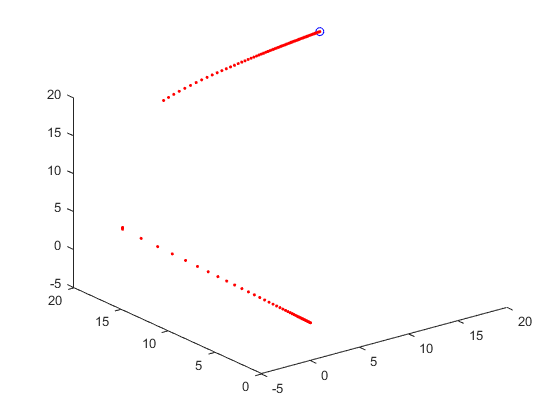

plot3(c(1,:),c(2,:),c(3,:),'.r')
hold off

Representación de los robots:

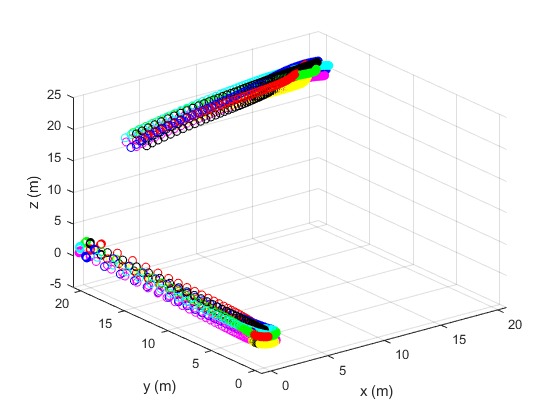

for g=1:N+3
    for z=2:iteration
        plot3(pos_rob(1,g,z),pos_rob(2,g,z),pos_rob(3,g,z),colors(g))
        hold on
    end
end
xlabel('x (m)')
ylabel('y (m)')
zlabel('z (m)')
grid on
hold off

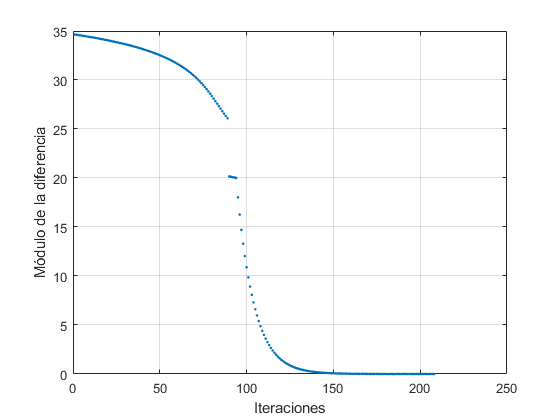

plot(1:length(mod_r_c),mod_r_c,".")
xlabel("Iteraciones")
ylabel("Módulo de la diferencia")
grid on

%error final para cada step-size
error=norm(c(:,length(mod_r_c))-r0)

error = 8.9581e-04

c0

c0 = 	1.0e+-3 *

    0.0076
   -0.1727
   -0.8790


M_max=max(M)

M_max = 0.0013

Representación de los robots en la última iteración:

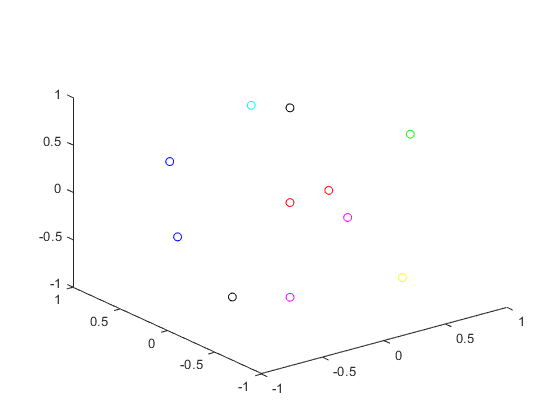

for p=1:N+3
    plot3(pos_rob(1,p,length(mod_r_c)),pos_rob(2,p,length(mod_r_c)),pos_rob(3,p,length(mod_r_c)),colors(p))
    hold on
end

Como se puede ver en la representación del centro, siempre hay un "salto", esto es, una gran diferencia entre el valor del centro anterior y el siguiente. Esto puede ser por el condicionamiento del Hessiano, aunque no estoy del todo seguro.